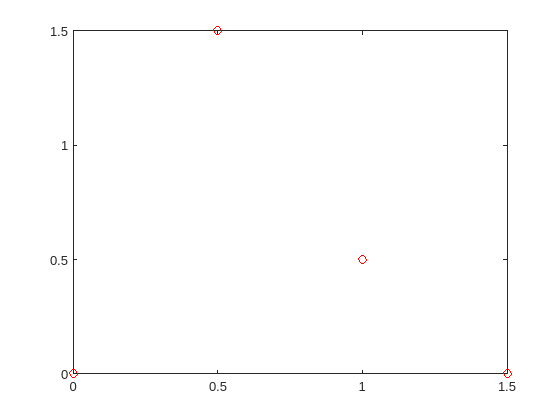

N = 100;

% path to follow: Mx2
% [x1 y1; x2 y2; x3 y3; ...]
path = [0 0; 0.5 1.5; 1 0.5; 1.5 0];
figure
plot(path(:, 1), path(:, 2), "ro")

ts = linspace(0, )
xs = interp1(, )


% design vector x
% [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
x0 = [zeros(7*N,1); 1];

costfcn = @(x) x(end);

% supply gradients and show iterations
options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'SpecifyObjectiveGradient', true, 'SpecifyConstraintGradient', true);
xstar = fmincon(@costfcn_w_grad, x0, [], [], [], [], [], [], @nonlcon_w_grad, options);


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



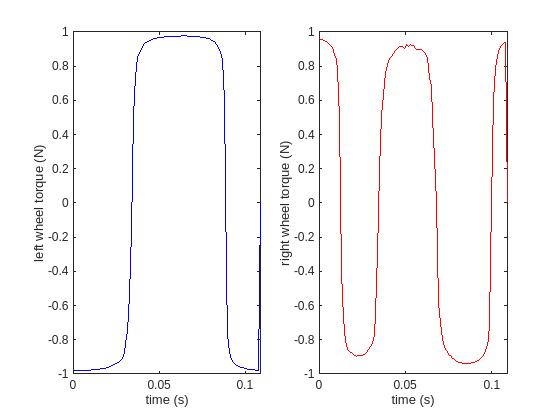


% Extract states from design vector
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);

% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

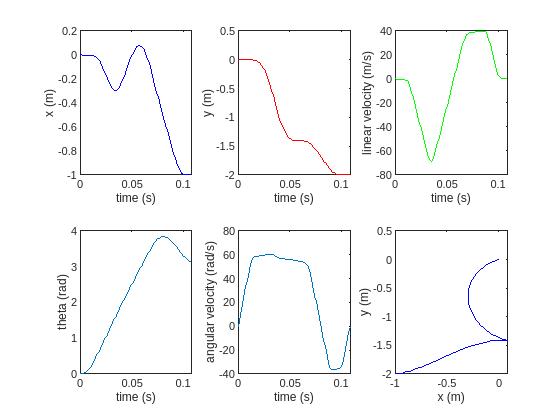


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

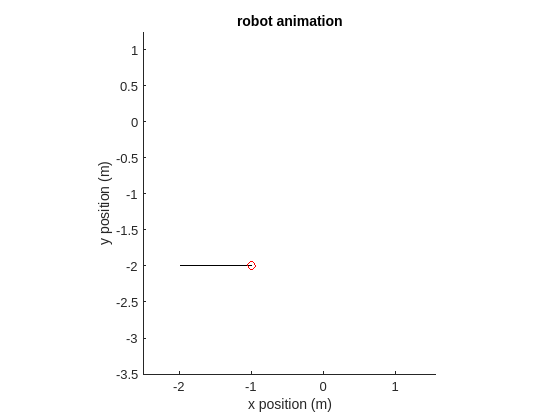


animate_direct_collocation(xstar)

% use symbolic toolbox to get cost and constraint function gradients
syms x [7*N+1 1]
matlabFunction(gradient(costfcn(x), x), "File", "costfcn_gradient.m");

[C, Ceq] = nonlcon(x);
matlabFunction(jacobian(C, x), "File", "nonlcon_c_jacobian.m", "Vars", {x});
matlabFunction(jacobian(Ceq, x), "File", "nonlcon_ceq_jacobian.m", "Vars", {x});

function [f, gradf] = costfcn_w_grad(x)
    f = x(end);
    gradf = costfcn_gradient();
end

function [C, Ceq, GC, GCeq] = nonlcon_w_grad(x)
    [C, Ceq] = nonlcon(x);
    GC = nonlcon_c_jacobian(x)';
    GCeq = nonlcon_ceq_jacobian(x)';
end